Upp=0;
Ypp=0;
Zskok=0;
imax = 250;

%Parametry dobrane eksperymentalnie
D=100; %D z poprzedniego podpunktu
N=70; 
Nu=4; 
lambda=4; 
Dz=61; %Dz z poprzedniego podpunktu
%dUmax = 1;

% init
Y = zeros(imax, 1);
U = zeros(imax, 1);
Yzad = zeros(imax,1);
Z = zeros(imax,1);
M = zeros(N, Nu);
Mp = zeros(N, D-1);
Mzp = zeros(N,Dz-1);
dUp = zeros(D-1, 1);
dZp = zeros(Dz-1, 1);
dU = zeros(Nu, 1);
Y0 = zeros(N, 1);
I = eye(Nu);
U(1:11) = Upp;
Yzad(1:9)=0;
Yzad(10:imax)=1;
Z(10:imax)= Zskok;


u = U - Upp;
y = zeros(imax, 1);
e = zeros(imax ,1);


Ydmc = zeros(N,1);
Ydmc_zad = zeros(N,1);

for i = 1:Nu
    M(i:N,i) = s(1:N-i+1);
end

for i=1:(D-1)
    Mp(1:N,i)=s(i+1:N+i)-s(i);
end
for i=1:(Dz-1)
    Mzp(1:N,i)=sz(i+1:N+i)-sz(i);
end

K = (M'*M + lambda*I)^(-1)*M';

for k = 10:imax
    Y(k)=symulacja_obiektu2y_p2(U(k-5),U(k-6),Z(k-3),Z(k-4),Y(k-1),Y(k-2));
    y(k) = Y(k) - Ypp;
    e(k) = Yzad(k) - Y(k);
   
    Ydmc_zad(1:N) = Yzad(k);
    Ydmc(1:N) = y(k);
    
    Y0 = Ydmc + Mp*dUp ; %+ Mzp*dZp;
    
    dU = K*(Ydmc_zad - Y0);
    du = dU(1);
    dz = dZ(1);
    
%     %ogr du
%     if du > dUmax
%         du = dUmax;
%     end
%     
%     if du < -dUmax
%         du = -dUmax;
%     end
    
    for n = D-1:-1:2
      dUp(n,1) = dUp(n-1,1);
    end
    dUp(1) = du;
    
    for n = Dz-1:-1:2
      dZp(n,1) = dZp(n-1,1);
    end
    dZp(1) = Z(k)-Z(k-1);
    
    u(k) = u(k-1) + du;
    
    % ogr umin, umax
    
%     if u(k) > Umax
%         u(k) = Umax;
%         dUp(1) = u(k) - u(k-1);
%     end
%     if u(k) < Umin
%         u(k) = Umin;
%         dUp(1) = u(k) - u(k-1);
%     end
    
    U(k) = u(k) + Upp;
    
end

E = (norm(e))^2

E = 9.7241

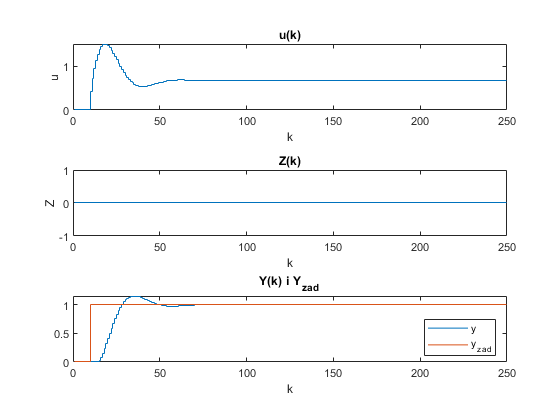


f5 = figure;
subplot(3,1,1);
stairs(U);
title('u(k)');
xlabel('k');
ylabel('u');
subplot(3,1,2);
stairs(Z);
title('Z(k)');
xlabel('k');
ylabel('Z');
subplot(3,1,3);
stairs(Y);
title('Y(k) i Y_z_a_d');
hold on;
stairs(Yzad);
xlabel('k');
legend('y','y_z_a_d','Location','southeast');

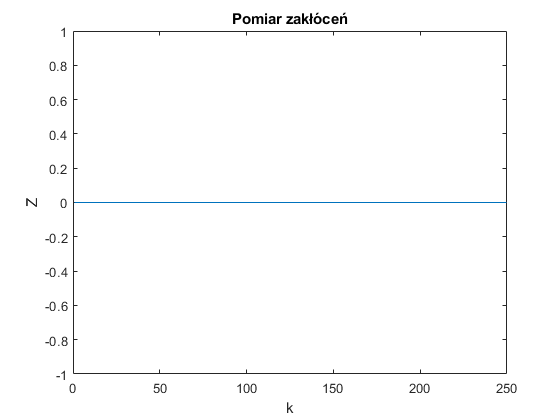


f6 = figure;
stairs(Z);
title('Pomiar zakłóceń');
xlabel('k');
ylabel('Z');

Zakłócenie Z = 1

%Punkty pracy
Upp=0;
Ypp=0;
Zskok=1;
imax = 250;

%Parametry dobrane eksperymentalnie
D=100; %D z poprzedniego podpunktu
N=70; 
Nu=4; 
lambda=4; 
Dz=61; %Dz z poprzedniego podpunktu
%dUmax = 1;

% init
Y = zeros(imax, 1);
U = zeros(imax, 1);
Yzad = zeros(imax,1);
Z = zeros(imax,1);
M = zeros(N, Nu);
Mp = zeros(N, D-1);
Mzp = zeros(N,Dz-1);
dUp = zeros(D-1, 1);
dZp = zeros(Dz-1, 1);
dU = zeros(Nu, 1);
Y0 = zeros(N, 1);
I = eye(Nu);
U(1:11) = Upp;
Yzad(1:9)=0;
Yzad(10:imax)=1;
Z(10:imax)=  Zskok;


u = U - Upp;
y = zeros(imax, 1);
e = zeros(imax ,1);


Ydmc = zeros(N,1);
Ydmc_zad = zeros(N,1);

for i = 1:Nu
    M(i:N,i) = s(1:N-i+1);
end

for i=1:(D-1)
    Mp(1:N,i)=s(i+1:N+i)-s(i);
end
for i=1:(Dz-1)
    Mzp(1:N,i)=sz(i+1:N+i)-sz(i);
end

K = (M'*M + lambda*I)^(-1)*M';

for k = 10:imax
    Y(k)=symulacja_obiektu2y_p2(U(k-5),U(k-6),Z(k-3),Z(k-4),Y(k-1),Y(k-2));
    y(k) = Y(k) - Ypp;
    e(k) = Yzad(k) - Y(k);
   
    Ydmc_zad(1:N) = Yzad(k);
    Ydmc(1:N) = y(k);
    
    Y0 = Ydmc + Mp*dUp + Mzp*dZp;
    
    dU = K*(Ydmc_zad - Y0);
    du = dU(1);
    dz = dZ(1);
    
%     %ogr du
%     if du > dUmax
%         du = dUmax;
%     end
%     
%     if du < -dUmax
%         du = -dUmax;
%     end
    
    for n = D-1:-1:2
      dUp(n,1) = dUp(n-1,1);
    end
    dUp(1) = du;
    
    for n = Dz-1:-1:2
      dZp(n,1) = dZp(n-1,1);
    end
    dZp(1) = Z(k)-Z(k-1);
    
    u(k) = u(k-1) + du;
    
    % ogr umin, umax
    
%     if u(k) > Umax
%         u(k) = Umax;
%         dUp(1) = u(k) - u(k-1);
%     end
%     if u(k) < Umin
%         u(k) = Umin;
%         dUp(1) = u(k) - u(k-1);
%     end
    
    U(k) = u(k) + Upp;
    
end

E = (norm(e))^2

E = 6.0189

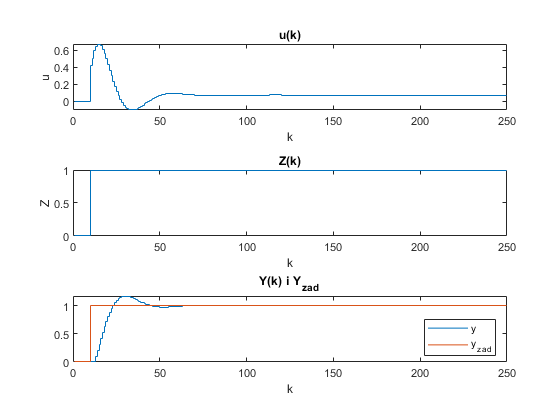


f9 = figure;
subplot(3,1,1);
stairs(U);
title('u(k)');
xlabel('k');
ylabel('u');
subplot(3,1,2);
stairs(Z);
title('Z(k)');
xlabel('k');
ylabel('Z');
subplot(3,1,3);
stairs(Y);
title('Y(k) i Y_z_a_d');
hold on;
stairs(Yzad);
xlabel('k');
legend('y','y_z_a_d','Location','southeast');

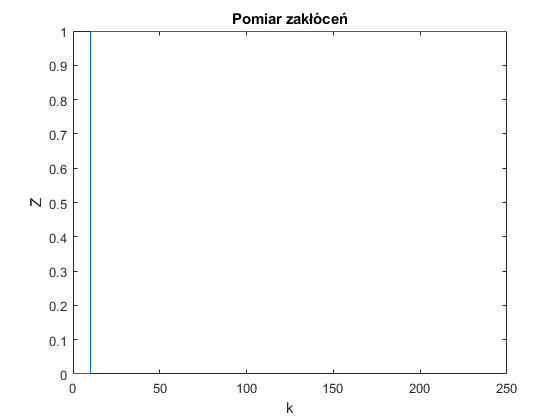


f10 = figure;
stairs(Z);
title('Pomiar zakłóceń');
xlabel('k');
ylabel('Z');

Z = 1 + część sinusoidalna (Zod 0.9 do 1.1)

Upp=0;
Ypp=0;
Zskok=1;
imax = 250;

%Parametry dobrane eksperymentalnie
D=120; %D z poprzedniego podpunktu
N=90; 
Nu=2; 
lambda=0.6; 
Dz=21; %zoptymalizowane
%dUmax = 1;

% init
Y = zeros(imax, 1);
U = zeros(imax, 1);
Yzad = zeros(imax,1);
Z = zeros(imax,1);
M = zeros(N, Nu);
Mp = zeros(N, D-1);
Mzp = zeros(N,Dz-1);
dUp = zeros(D-1, 1);
dZp = zeros(Dz-1, 1);
dU = zeros(Nu, 1);
Y0 = zeros(N, 1);
I = eye(Nu);
U(1:11) = Upp;
Yzad(1:9)=0;
Yzad(10:imax)=1;
Z(10:imax)=  Zskok + 0.1*sin(20*linspace(0,1,imax-9));


u = U - Upp;
y = zeros(imax, 1);
e = zeros(imax ,1);


Ydmc = zeros(N,1);
Ydmc_zad = zeros(N,1);

for i = 1:Nu
    M(i:N,i) = s(1:N-i+1);
end

for i=1:(D-1)
    Mp(1:N,i)=s(i+1:N+i)-s(i);
end
for i=1:(Dz-1)
    Mzp(1:N,i)=sz(i+1:N+i)-sz(i);
end

K = (M'*M + lambda*I)^(-1)*M';

for k = 10:imax
    Y(k)=symulacja_obiektu2y_p2(U(k-5),U(k-6),Z(k-3),Z(k-4),Y(k-1),Y(k-2));
    y(k) = Y(k) - Ypp;
    e(k) = Yzad(k) - Y(k);
   
    Ydmc_zad(1:N) = Yzad(k);
    Ydmc(1:N) = y(k);
    
    Y0 = Ydmc + Mp*dUp + Mzp*dZp;
    
    dU = K*(Ydmc_zad - Y0);
    du = dU(1);
    dz = dZ(1);
    
%     %ogr du
%     if du > dUmax
%         du = dUmax;
%     end
%     
%     if du < -dUmax
%         du = -dUmax;
%     end
    
    for n = D-1:-1:2
      dUp(n,1) = dUp(n-1,1);
    end
    dUp(1) = du;
    
    for n = Dz-1:-1:2
      dZp(n,1) = dZp(n-1,1);
    end
    dZp(1) = Z(k)-Z(k-1);
    
    u(k) = u(k-1) + du;
    
    % ogr umin, umax
    
%     if u(k) > Umax
%         u(k) = Umax;
%         dUp(1) = u(k) - u(k-1);
%     end
%     if u(k) < Umin
%         u(k) = Umin;
%         dUp(1) = u(k) - u(k-1);
%     end
    
    U(k) = u(k) + Upp;
    
end

E = (norm(e))^2

E = 5.7320

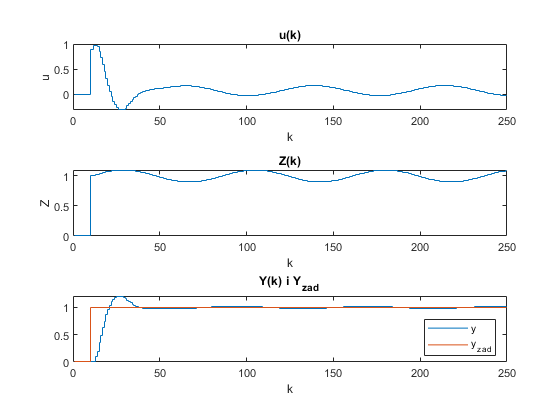


f9 = figure;
subplot(3,1,1);
stairs(U);
title('u(k)');
xlabel('k');
ylabel('u');
subplot(3,1,2);
stairs(Z);
title('Z(k)');
xlabel('k');
ylabel('Z');
subplot(3,1,3);
stairs(Y);
title('Y(k) i Y_z_a_d');
hold on;
stairs(Yzad);
xlabel('k');
legend('y','y_z_a_d','Location','southeast');

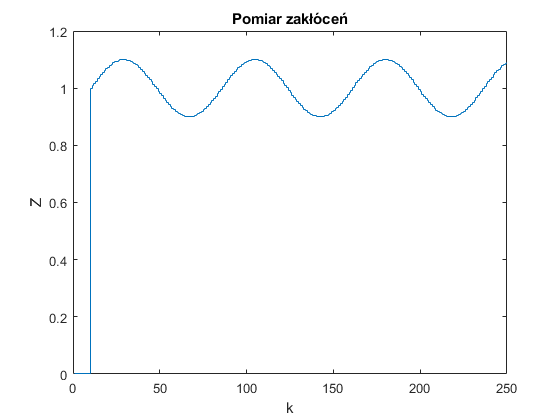


f10 = figure;
stairs(Z);
title('Pomiar zakłóceń');
xlabel('k');
ylabel('Z');